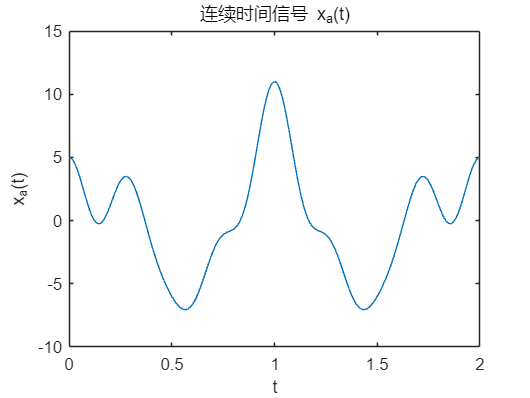

% 连续时间信号
t = 0:0.01:2; % 时间范围
Omega1 = 2*pi;
Omega2 = 3*pi;
Omega3 = 6*pi;
Omega4 = 8*pi;
xa_t = 5*cos(Omega1*t) - 3*cos(Omega2*t) + 2*cos(Omega3*t) + cos(Omega4*t);
figure;
plot(t, xa_t);
title('连续时间信号 x_a(t)');
xlabel('t');
ylabel('x_a(t)');

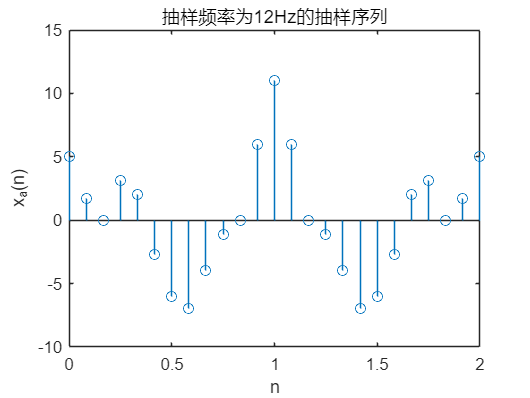


% 奈奎斯特抽样频率
% 信号的最高频率为 8π，因此奈奎斯特抽样频率为 2 * 8π / (2π) = 8Hz

% 抽样频率为12Hz和20Hz的抽样序列
fs1 = 12; % 抽样频率12Hz
fs2 = 20; % 抽样频率20Hz
n1 = 0:1/fs1:2; % 12Hz抽样时间点
n2 = 0:1/fs2:2; % 20Hz抽样时间点
xa_n1 = 5*cos(Omega1*n1) - 3*cos(Omega2*n1) + 2*cos(Omega3*n1) + cos(Omega4*n1);
xa_n2 = 5*cos(Omega1*n2) - 3*cos(Omega2*n2) + 2*cos(Omega3*n2) + cos(Omega4*n2);

figure;
stem(n1, xa_n1);
title('抽样频率为12Hz的抽样序列');
xlabel('n');
ylabel('x_a(n)');

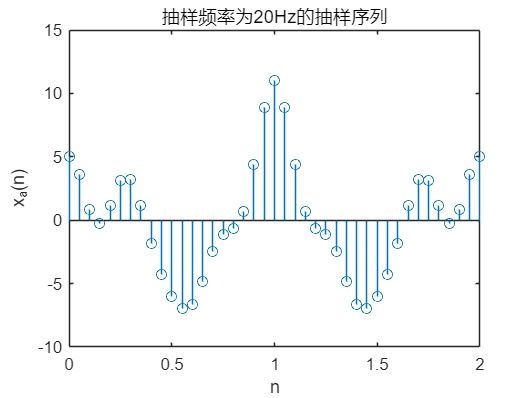


figure;
stem(n2, xa_n2);
title('抽样频率为20Hz的抽样序列');
xlabel('n');
ylabel('x_a(n)');